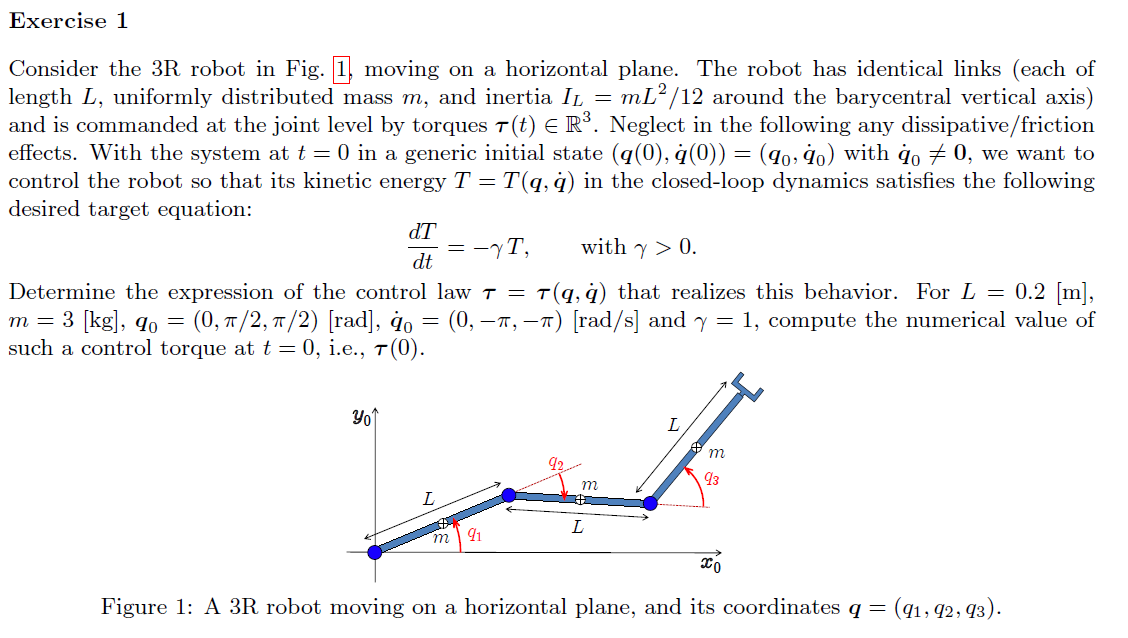

% clear all, clc, close all
% % This part is isolated from previous sectionclear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,1,1];
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% 
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% % g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% % g=[0,-g0*sin(alpha_angle),0]';
% g=[0,0,-g0]';
% R2Robot=['rrr';'xxx';sigma]    
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% 
% z.q=q;
% z.q_dot=q_dot;
% 
% z.dc=dc;
% 
% z.I=I;
% z.methodD=1%with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% z.l=l;
%  z.m=m;
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;

% %% the following assumptions are due to the inexistence of l1 and dc1   
% L=sym('L','real');
% m_mass=sym('m','real');
% Dc=sym('dc','real');
% 
% % l(:)=L
% % m(:)=m_mass
% % dc(:)=Dc
% % I(:)=m*L^2/12
% % z.m=m;
% % z.l=l;
% % z.I=I;
% % z.dc=dc;
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z);
% T
% Ti
% M

## Computing values

% 

% gamma=sym('gamma','real')
% 
% l_=[L,L,L]'
% m_=[m_mass,m_mass,m_mass]'
% dc_=[Dc,Dc,Dc]'
% I_=I;
% I_(:)=m_mass*L^2/12
% gamma_=1
% m_mass_=3
% L_=0.2
% Dc_=L_/2
% q_=[0,pi/2,pi/2]'
% q_dot_=[0,-pi,-pi]'
% vars2replace=[m;l;dc;I]
% vars2replace_=[m_;l_;dc_;I_]
% M_=simplify(subs(M,vars2replace,vars2replace_))
% 
% vars2replace2=[L;m_mass;Dc;q;q_dot]
% vars2replace2_=[L_;m_mass_;Dc_;q_;q_dot]
% M2_=simplify(subs(M_,vars2replace2,vars2replace2_))

## linearization

% % [Msubs, dynamicParamsReturn, a] = getDynamicParameters(M,q,[])

## torque control law

% tau=-gamma/2*(M2_*q_dot_)
% tau_=-gamma_/2*(M2_*q_dot_)
% vpa(tau_)

## exercise 2

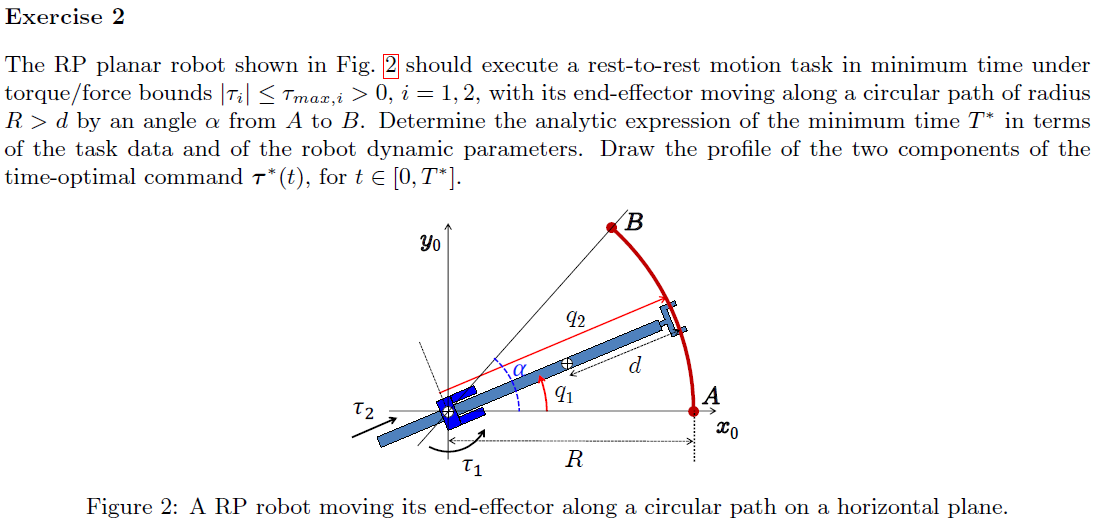

clear all, clc, close all
% This part is isolated from previous sectionclear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [1,0];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
% 
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');

m_p = sym('m_p','real');
d = sym('d','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
% g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% g=[0,-g0*sin(alpha_angle),0]';
g=[0,0,-g0]';
R2Robot=['rp';'xx';sigma]    

R2Robot = 3×2 char array
    'rp'
    'xx'
    ' '


z = Gen_param(n);
z.sigmaD=R2Robot;

z.q=q;
z.q_dot=q_dot;

z.dc=dc;

z.I=I;
z.methodD=1%with DH table

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: []
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: []
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismotor: 0
              motor_only: 0


% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.l=l;
 z.m=m;
z.opt_expr={[l(1),dc'],[0,0,d]};
% z.rcdefined=true;
z.prismatic_CoM_method=[1,2];1%% normal mode onle CoM=dc(i) in %% 2 inverse mdoe CoM=q(i)-dc(i) %% for the moment only for prismatics

ans = 1

## computing M

[Pc,vc,w,T,Ti,M] = getGenericPC2(z);

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [1×2 sym]
               rcdefined: 1
                opt_expr: {[1×3 sym]  [1×3 sym]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 2]
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismot

si falla aquí está el error


anglerot = 1×2 cell array
    {4×4 sym}    {4×4 sym}


method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{2}\,\left(\left(d^{2}-2\,d\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} \end{array}\right)$$

$$To\_derive = \left(\begin{array}{cc} -\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \cos\left(q_{1}\left(t\right)\right)\\ \cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \sin\left(q_{1}\left(t\right)\right)\\ 0 & 0 \end{array}\right)$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]


z_derivated = struct with fields:
     dot_t: [3×2 sym]
    ddot_t: [3×2 sym]
    tdot_t: [3×2 sym]


z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×2 sym]
       ddot_t: [3×2 sym]
       tdot_t: [3×2 sym]
          dot: [3×2 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×2 sym]
        ddot_t: [3×2 sym]
        tdot_t: [3×2 sym]
           dot: [3×2 sym]
     dot_short: []
          ddot: [3×2 sym]
    ddot_short: []
          tdot: [3×2 sym]
    tdot_short: []


T

$$T = \frac{m_{2}\,\left(\left(d^{2}-2\,d\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}$$

Ti(:)

$$ans = \left(\begin{array}{c} \frac{I_{1}\,{{\dot{q}}_{1}}^{2}}{2}\\ \frac{m_{2}\,\left(\left(d^{2}-2\,d\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} \end{array}\right)$$

M

$$M = \left(\begin{array}{cc} m_{2}\,d^{2}-2\,m_{2}\,d\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2} & 0\\ 0 & m_{2} \end{array}\right)$$

[C,cac,Csubs,S] = getCs(M,q,q_dot);

>> Getting  the Christoffel’sym. Might take a while...


cac

$$cac = \left(\begin{array}{c} -2\,m_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(d-q_{2}\right)\\ m_{2}\,{{\dot{q}}_{1}}^{2}\,\left(d-q_{2}\right) \end{array}\right)$$

% [C,cac,Csubs] = getCs(Msubs,q',qd')
tau =simplify( M*q_ddot + cac);

tau_=subs(tau)

$$tau\_ = \left(\begin{array}{c} {\ddot{q}}_{1}\,\left(m_{2}\,d^{2}-2\,m_{2}\,d\,q_{2}+m_{2}\,{q_{2}}^{2}+I_{1}+I_{2}\right)-2\,m_{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(d-q_{2}\right)\\ m_{2}\,\left(d-q_{2}\right)\,{{\dot{q}}_{1}}^{2}+m_{2}\,{\ddot{q}}_{2} \end{array}\right)$$

C{:}

$$ans = \left(\begin{array}{cc} 0 & -m_{2}\,\left(d-q_{2}\right)\\ -m_{2}\,\left(d-q_{2}\right) & 0 \end{array}\right)$$

$$ans = \left(\begin{array}{cc} m_{2}\,\left(d-q_{2}\right) & 0\\ 0 & 0 \end{array}\right)$$

R=sym('R','real')

$$R = R$$

vars2replace =[q(2);q_dot(1)]

$$vars2replace = \left(\begin{array}{c} q_{2}\\ {\dot{q}}_{1} \end{array}\right)$$

vars2replace_=[R;0]

$$vars2replace\_ = \left(\begin{array}{c} R\\ 0 \end{array}\right)$$

tau_=subs(tau,vars2replace,vars2replace_)

$$tau\_ = \left(\begin{array}{c} {\ddot{q}}_{1}\,\left(m_{2}\,R^{2}-2\,m_{2}\,R\,d+m_{2}\,d^{2}+I_{1}+I_{2}\right)\\ m_{2}\,{\ddot{q}}_{2} \end{array}\right)$$

## bang cost bang profile

clear all;
close all;
clc;
T=sym('T','real');
V1=sym('V1','real');
A1=sym('A1','real');
A1_=2;
T_=2;
Ts=T/4;
V1=Ts*A1;
V1_=1;
qA=[0,1]'

qA =      0
     1


qB=sym('qB',[2,1],'real');

I_0=1

I_0 = 1

[qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)

$$qa\_piece1 = \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ 0 & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ A_{1}\,\mathrm{Ts} & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ A_{1}\,\mathrm{Ts}-A_{1}\,\left(\mathrm{Ts}-T+t\right) & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\mathrm{Ts}\wedge 0\leq t\\ -\frac{A_{1}\,\mathrm{Ts}\,\left(\mathrm{Ts}-2\,t\right)}{2} & \text{ if }\mathrm{Ts}\leq t\wedge \mathrm{Ts}+t<T\\ -\frac{A_{1}\,\left(T^{2}-2\,T\,\mathrm{Ts}-2\,T\,t+2\,{\mathrm{Ts}}^{2}+t^{2}\right)}{2} & \text{ if }t\leq T\wedge T-\mathrm{Ts}\leq t \end{array}\right. \end{array}\right)$$

$$qa\_piece2 = \begin{array}{l} \left(\begin{array}{c} \left\{ \begin{array}{cl} A_{1} & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ 0 & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ -A_{1} & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} A_{1}\,t & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ V_{1} & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ A_{1}\,\left(T-t\right) & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right.\\ \left\{ \begin{array}{cl} \frac{A_{1}\,t^{2}}{2} & \text{ if }t<\frac{V_{1}}{A_{1}}\wedge 0\leq t\\ \frac{V_{1}\,\left(2\,t-\frac{V_{1}}{A_{1}}\right)}{2} & \text{ if }\frac{V_{1}}{A_{1}}\leq t\wedge \sigma_{1}<T\\ -\frac{A_{1}\,\left(T^{2}-2\,T\,t+\frac{2\,{V_{1}}^{2}}{{A_{1}}^{2}}+t^{2}-\frac{2\,T\,V_{1}}{A_{1}}\right)}{2} & \text{ if }t\leq T\wedge T-\frac{V_{1}}{A_{1}}\leq t \end{array}\right. \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{V_{1}+A_{1}\,t}{A_{1}} \end{array}$$

$$qa\_piece2 = \left(\begin{array}{c} \left\{ \begin{array}{cl} 2.0 & \text{ if }t\in \left[0.0,0.5\right)\\ 0.0 & \text{ if }t\in \left[0.5,1.5\right)\\ -2.0 & \text{ if }t\in \left[1.5,2.0\right] \end{array}\right.\\ \left\{ \begin{array}{cl} 2.0\,t & \text{ if }t\in \left[0.0,0.5\right)\\ 1.0 & \text{ if }t\in \left[0.5,1.5\right)\\ 4.0-2.0\,t & \text{ if }t\in \left[1.5,2.0\right] \end{array}\right.\\ \left\{ \begin{array}{cl} t^{2} & \text{ if }t\in \left[0.0,0.5\right)\\ t-0.25 & \text{ if }t\in \left[0.5,1.5\right)\\ -1.0\,t^{2}+4.0\,t-2.5 & \text{ if }t\in \left[1.5,2.0\right] \end{array}\right. \end{array}\right)$$

T_ = 2

Ts_ = 0.5000

$$t = t$$

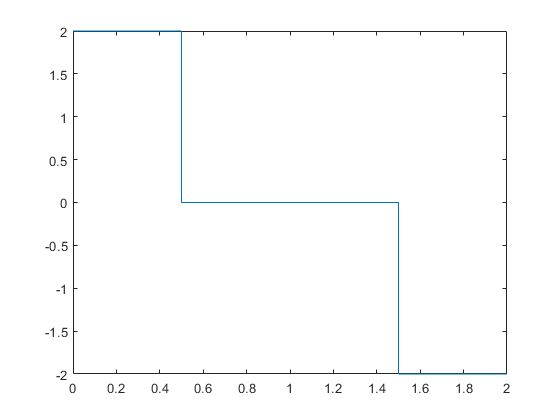

fplot(qa_piece2(1,:),[0,T_])

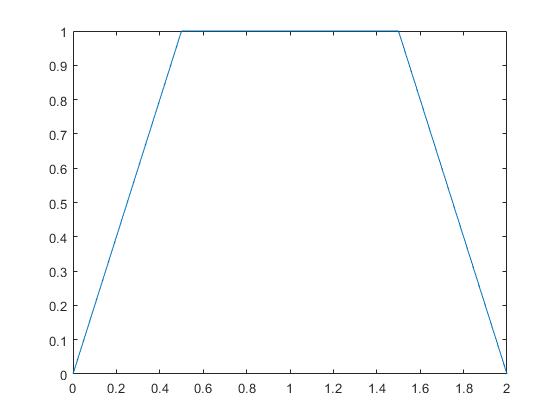

figure
fplot(qa_piece2(2,:),[0,T_])

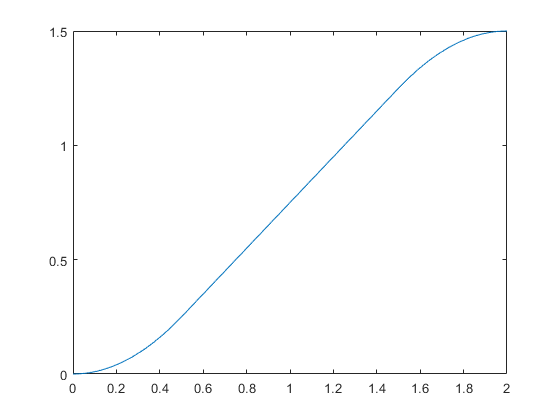

figure
fplot(qa_piece2(3,:),[0,T_])

figure
% [qa_piece2,T_,Ts_] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% tau_2=int(qa_piece2,t)

## tau 2

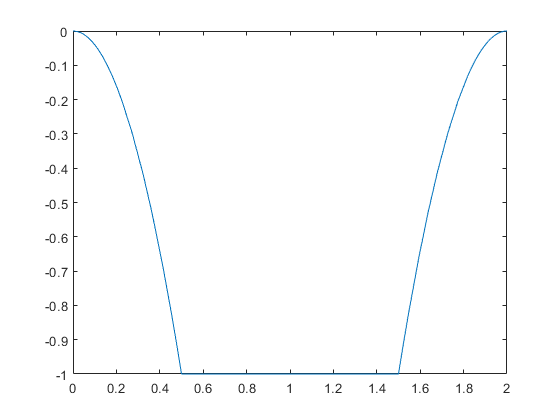


fplot(-qa_piece2(2,:).^2,[0,T_])